## Esercizio 1

clear; clc; close all;

### Rappresentazione ingresso-stato-uscita

num = [-1 2];
den = [1 4.3 1.2];
G = tf(num,den);

processo = ss(G);
A = processo.A;
B = processo.B;
C = processo.C;
D = processo.D;

### Analisi del sistema a ciclo aperto e a ciclo chiuso

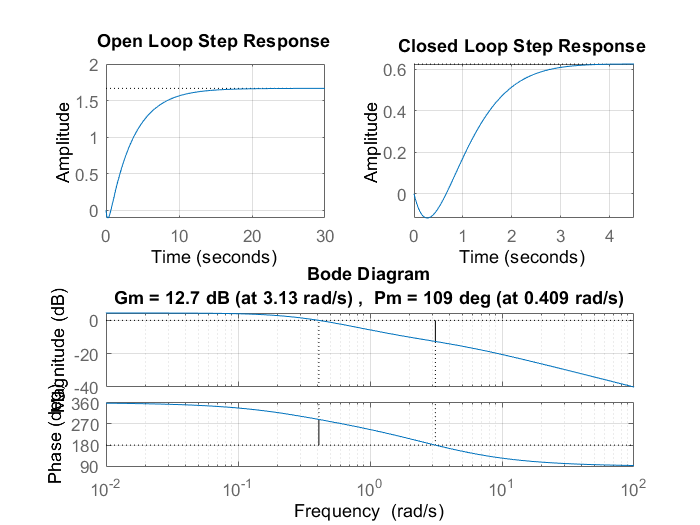

figure(1);
subplot(2,2,1);
step(G); title( "Open Loop Step Response" ); grid;
subplot(2,2,2);
step(feedback(G,1)); title( "Closed Loop Step Response" ); grid;
subplot(2,2,[3,4]); margin(G); grid;

### Taratura del tempo di campionamento Tc

roots = roots(den);
if roots(1)>=roots(2)
    polo_dominante = roots(1);
else
    polo_dominante = roots(2);
end
cost_temp_polo_dominante = -1/polo_dominante;

ta = 3*cost_temp_polo_dominante;
wbw = 1/cost_temp_polo_dominante;
tr = (0.8*pi)/wbw;

estremo_sinistro_trTc = tr/20;
estremo_destro_trTc = tr/10;

estremo_sinistro_wbwTc = pi/(50*wbw);
estremo_destro_wbwTc = pi/(10*wbw);

Tc = 0.45;

### Metodo di Ziegler-Nichols ad anello chiuso

#### Kcr e Tcr per ispezione supponendo di non conoscere il sistema

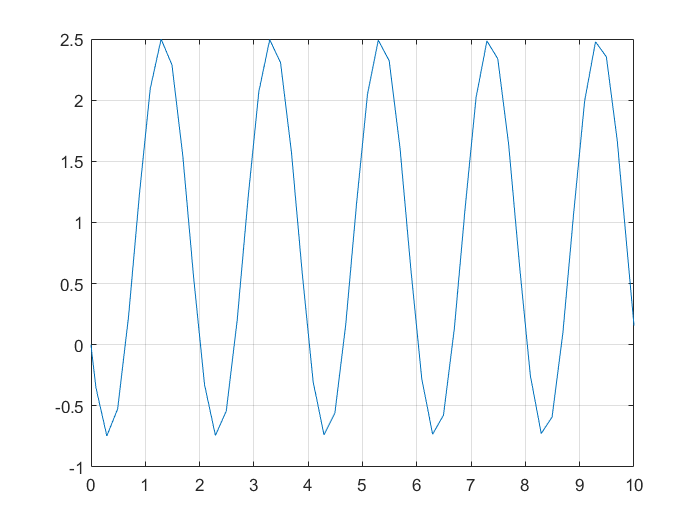

Kcr = 4.3;
simulazione = sim('IMPIANTO_INSTABILE_Kcr');
figure(2);
plot(simulazione.Y.Time,simulazione.Y.Data);
grid;

Tcr = 2;

#### Kcr e Tcr tramite Nyquist supponendo di conoscere il sistema

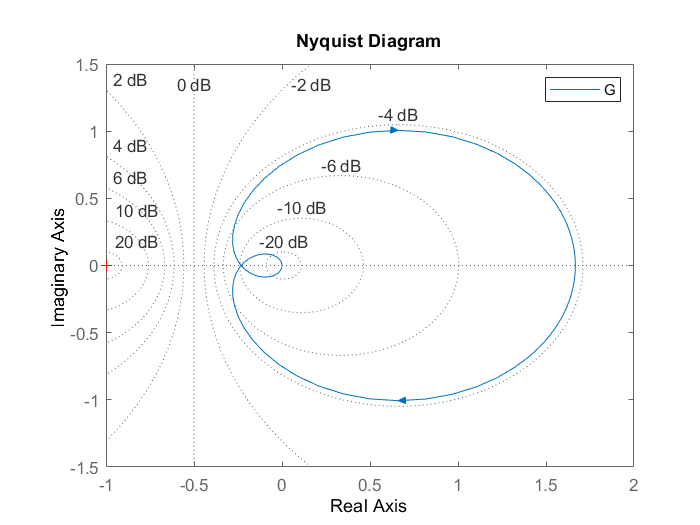

figure(2);
nyquist(G);
grid;
legend;

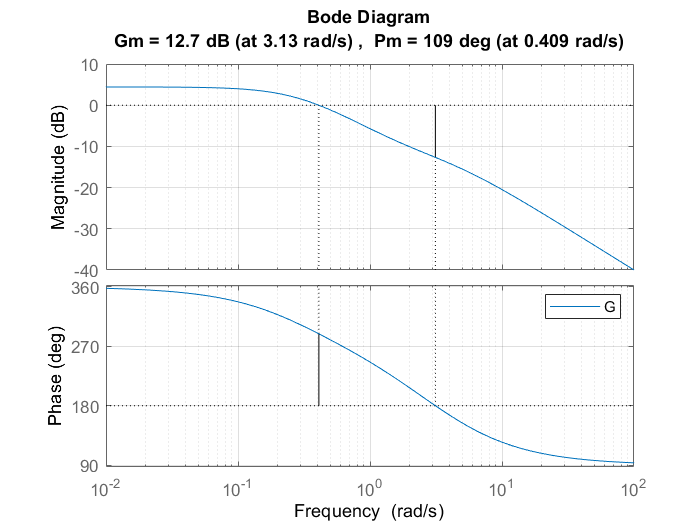

realNy = -0.232;
O = 0;
OA = O-realNy;
mA = 1/OA;
Kcr = mA;

figure(3);
margin(G);
grid;
legend;

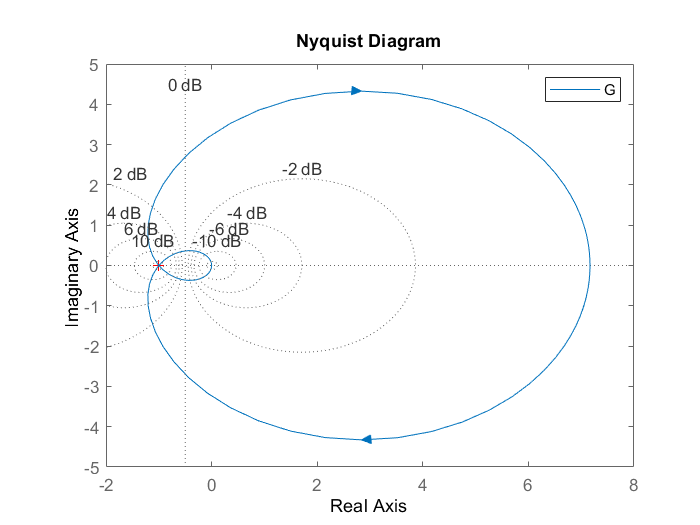

Kcr = margin(G);


figure(5);
nyquist(Kcr*G);
grid;
legend('G');

### Taratura dei parametri del regolatore

KP_P = 0.5*Kcr;

KP_PI = 0.45*Kcr;
TI_PI = 0.85*Tcr;

KP_PID = 0.6*Kcr;
TI_PID = 0.5*Tcr;
TD_PID = 0.12*Tcr;

N = 100;
T = ta/40;


continuos = sim('continuos');
yc = continuos;
discrete = sim('discrete');
yd = discrete;

### Regolatore Standard P

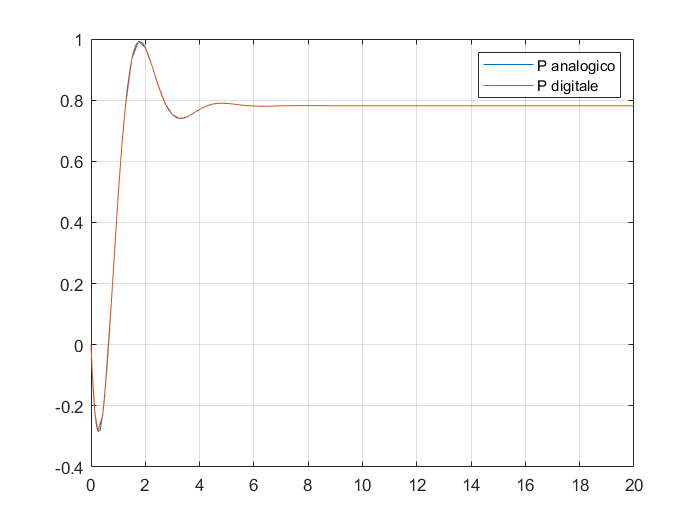

figure(6);
plot(yc.P.Time,yc.P.Data);
hold on
plot(yd.P.Time,yd.P.Data);
grid;
legend('P analogico','P digitale');

### Regolatore Standard PI

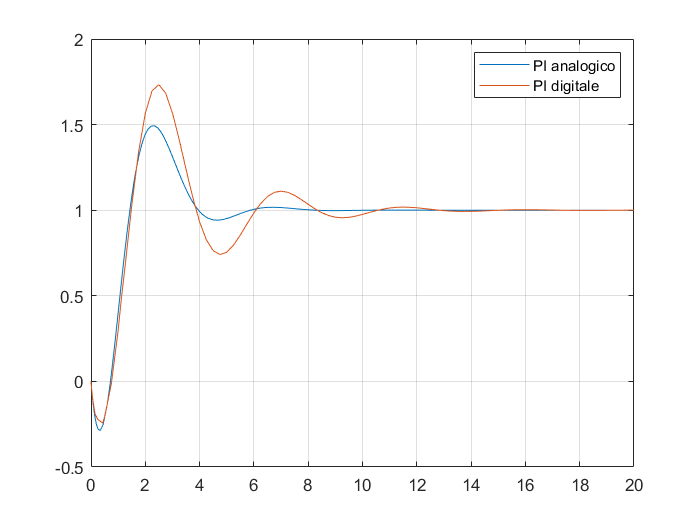

figure(7);
plot(yc.PI.Time,yc.PI.Data);
hold on
plot(yd.PI.Time,yd.PI.Data);
grid;
legend('PI analogico','PI digitale');

### Regolatore Standard PID

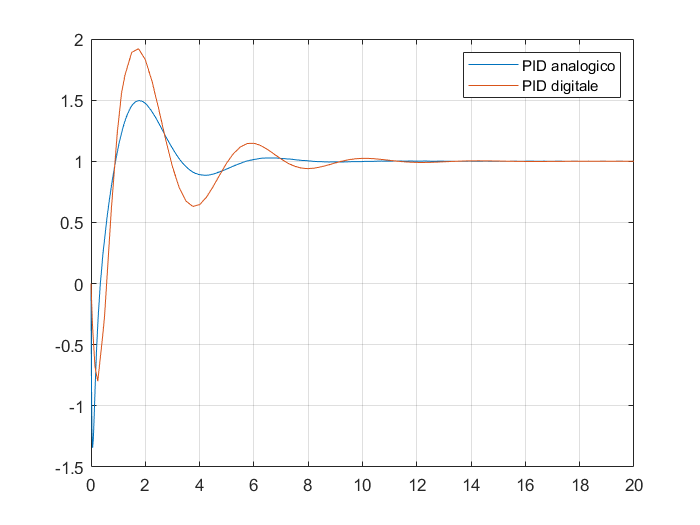

figure(8);
plot(yc.PID.Time,yc.PID.Data);
hold on
plot(yd.PID.Time,yd.PID.Data);
grid;
legend('PID analogico','PID digitale');

### Regolatori Standard Analogici

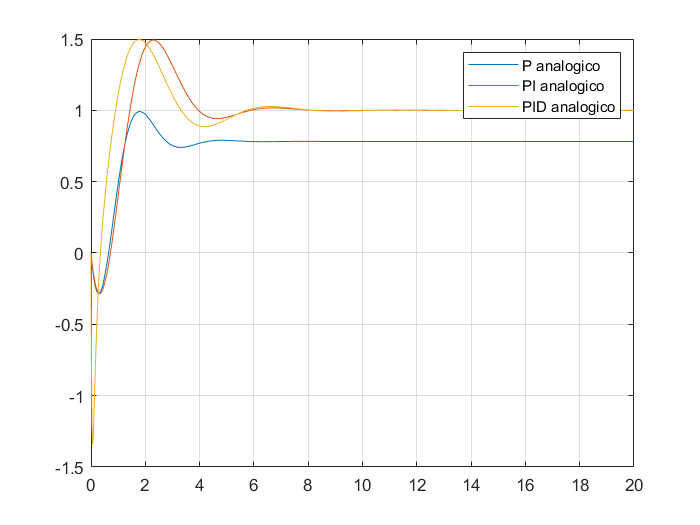

figure(9);
title('continuos');
plot(yc.P.Time,yc.P.Data);
hold on
plot(yc.PI.Time,yc.PI.Data);
hold on
plot(yc.PID.Time,yc.PID.Data);
legend('P analogico','PI analogico','PID analogico');
grid;

### Regolatori Standard Digitali

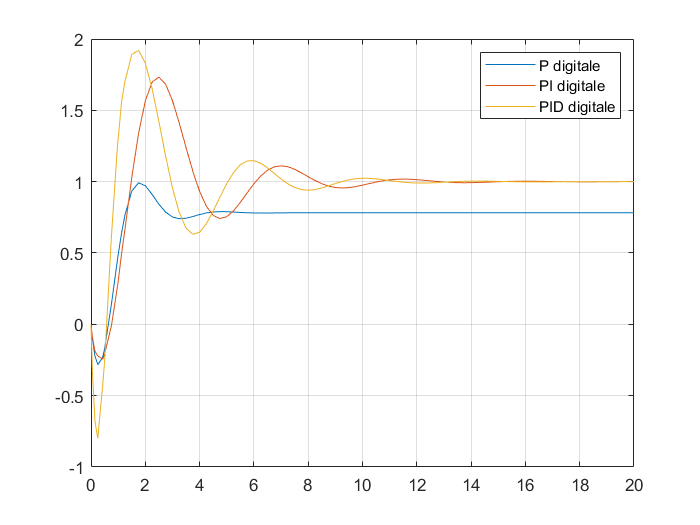

figure(10);
title('discrete');
plot(yd.P.Time,yd.P.Data);
hold on
plot(yd.PI.Time,yd.PI.Data);
hold on
plot(yd.PID.Time,yd.PID.Data);
legend('P digitale','PI digitale','PID digitale');
grid;

### PID Tuner

KP_P_analogico_tuned = 1.47219531686421;

KP_P_digitale_tuned = 1.47219531686421;


KP_PI_analogico_tuned = 1.47593963796892;
I_PI_analogico_tuned = 0.325410877804267;

KP_PI_digitale_tuned = 1.4003674925568;
I_PI_digitale_tuned = 0.28478840442912;


KP_PID_analogico_tuned = 1.9364815341473;
I_PID_analogico_tuned = 0.279951410984123;
TD_PID_analogico_tuned = 0.0554825984150835;

KP_PID_digitale_tuned = 1.83497063890365;
I_PID_digitale_tuned = 0.172208500364823;
TD_PID_digitale_tuned = 0.0992484035615046;


tuned = sim('tuned');
yt = tuned;

#### Regolatore Standard P analogico

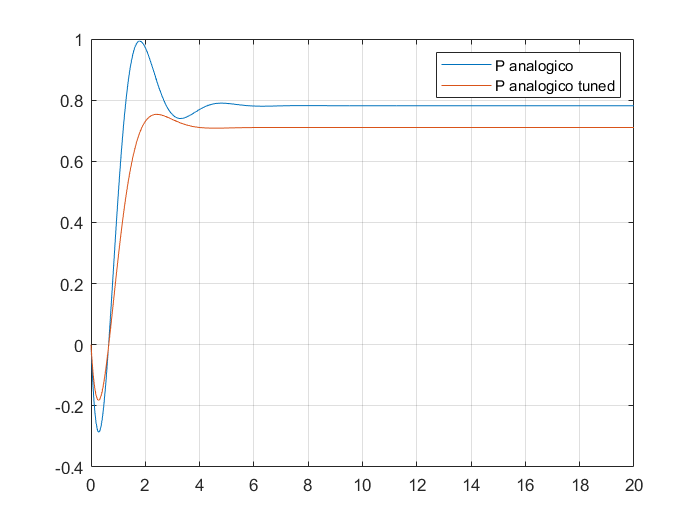

figure(11);
plot(yt.Panalogico.Time,yt.Panalogico.Data);
grid;
legend('P analogico','P analogico tuned');

#### Regolatore Standard P digitale

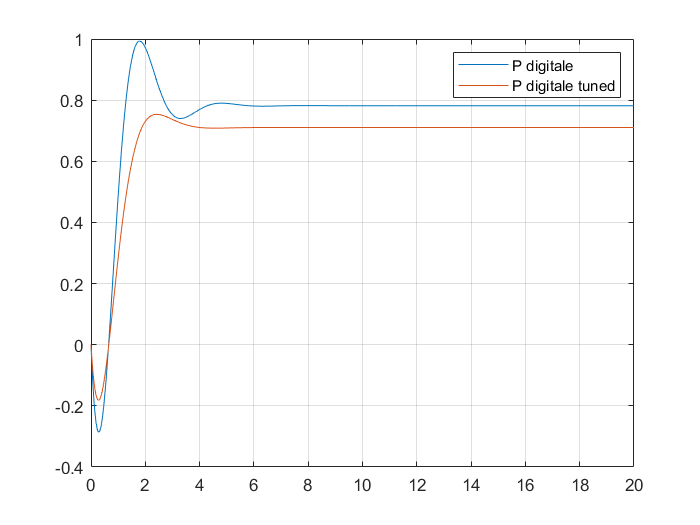

figure(12);
plot(yt.Pdigitale.Time,yt.Pdigitale.Data);
grid;
legend('P digitale','P digitale tuned');

#### Regolatore Standard PI analogico

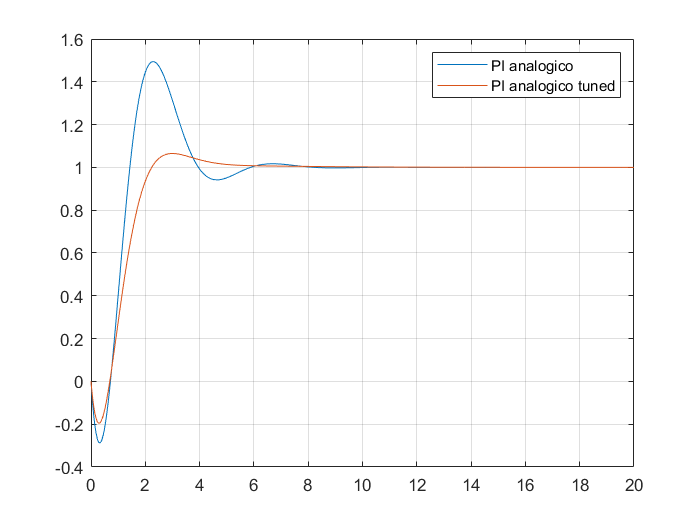

figure(13);
plot(yt.PIanalogico.Time,yt.PIanalogico.Data);
grid;
legend('PI analogico','PI analogico tuned');

#### Regolatore Standard PI digitale

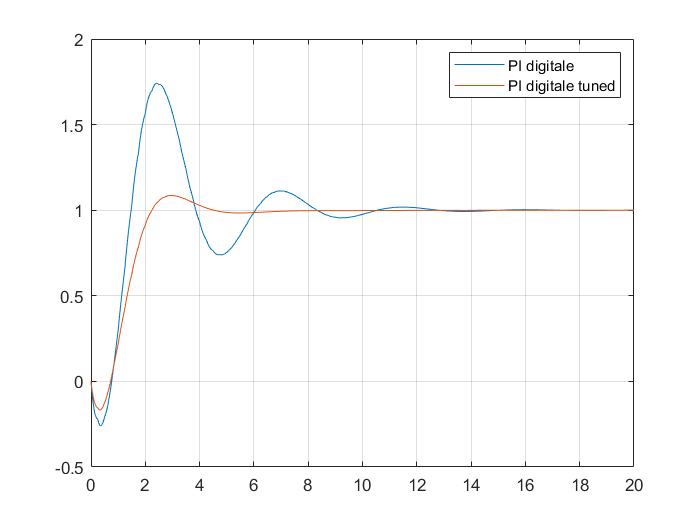

figure(14);
plot(yt.PIdigitale.Time,yt.PIdigitale.Data);
grid;
legend('PI digitale','PI digitale tuned');

#### Regolatore Standard PID analogico

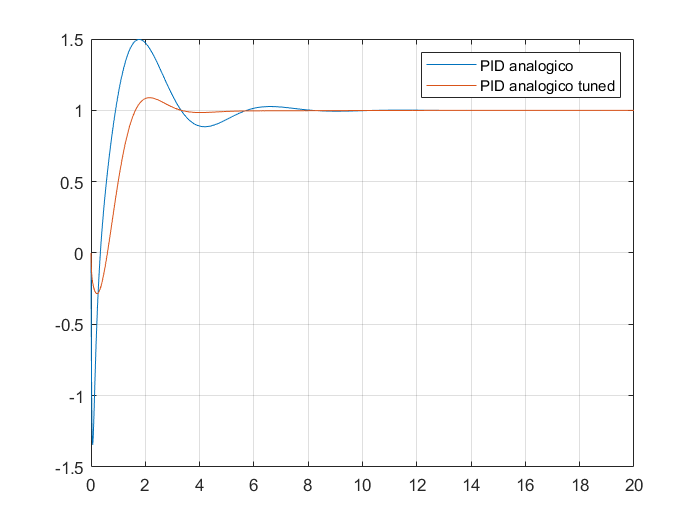

figure(15);
plot(yt.PIDanalogico.Time,yt.PIDanalogico.Data);
grid;
legend('PID analogico','PID analogico tuned');

#### Regolatore Standard PID digitale

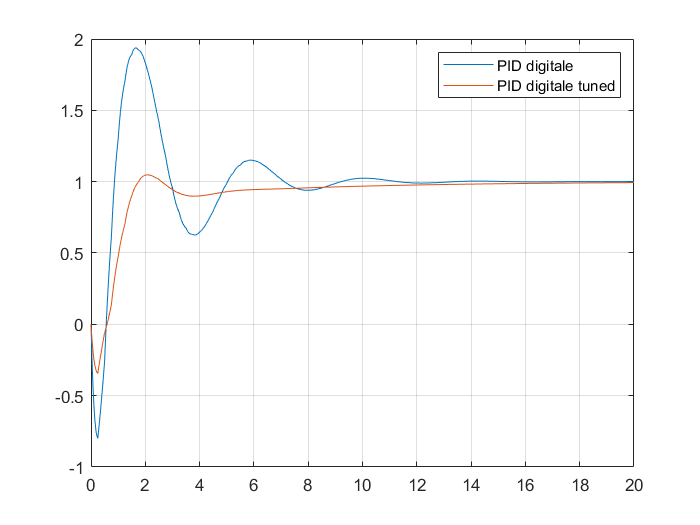

figure(16);
plot(yt.PIDdigitale.Time,yt.PIDdigitale.Data);
grid;
legend('PID digitale','PID digitale tuned');